# Net Tow Analysis - Kristiansen & Faltinsen Screen Model (Quasi-static)

Solves equilibrium pitch angle theta (0..90 deg) from moment balance about tow point at center of top (floater) rod, then computes drag/lift.

Geometry: - Flow is +x (horizontal) - theta = 0: panel is vertical, normal to flow (max drag) - theta -> 90deg: panel aligns with flow (min drag)

Tow point: center of TOP rod. Net hangs between TOP rod (floater) and BOTTOM rod (sinker).

clear; clc; close all;

## -------------------- INPUTS --------------------

Net geometry

net_width   = 0.60;      % [m]
net_depth   = 0.60;      % [m] vertical span between rods
dw          = 0.001;     % [m] twine diameter
lw          = 0.015;     % [m] mesh spacing parameter

% Rods
rod_length  = 0.75;      % [m]
rod_OD      = 0.02;      % [m]
rod_wall    = 0.0015;    % [m] (used only if you want metal volume)
rod_mass    = 0.150;     % [kg] each rod mass in air
net_mass    = 0.070;     % [kg] net mass in air

% Fluid (freshwater)
rho         = 1000;      % [kg/m^3]
nu          = 1e-6;      % [m^2/s]
g           = 9.81;

% Velocities
U_array     = linspace(0.1, 0.5, 9);

% Harmonics (net-specific tuning, paper suggests small values)
a3          = 0.05;      % 0..0.1
b4          = 0.05;      % 0..0.1

% Geometry for moment arms (about tow point at top rod center)
% Assume hydrodynamic resultant acts at net centroid (first-order model)
x_cp_frac   = 0.5;       % along net depth from top [0..1]
x_cg_net    = 0.5;       % net CG at centroid
x_cg_sinker = 1.0;       % sinker rod CG at bottom rod center

% Rod displacement assumption (IMPORTANT):
% If top rod is truly a "floater", it likely displaces FULL outer volume (sealed).
% If rods are open-ended and flood, they displace only metal volume.
rod_sealed  = true;      % <-- set TRUE if sealed/air-trapped, FALSE if flooded

## -------------------- DERIVED --------------------

A_net = net_width * net_depth;

% Solidity (square net)
Sn = 2*(dw/lw) - (dw/lw)^2;

% Effective submerged weights (weight - buoyancy)
% Net: approximate as nylon (you can replace with measured submerged weight)
rho_net_mat = 1140;                      % [kg/m^3] rough nylon
V_net_mat   = net_mass / rho_net_mat;
W_net_eff   = net_mass*g - rho*V_net_mat*g;   % [N] positive means sinks

% Rod displaced volume
rod_ID = rod_OD - 2*rod_wall;
V_outer = (pi/4)*rod_OD^2 * rod_length;

if rod_sealed
    V_disp_rod = V_outer;                % sealed: displaces full outer volume
else
    A_metal = (pi/4)*(rod_OD^2 - rod_ID^2);
    V_disp_rod = A_metal * rod_length;   % flooded: displaces only metal volume
end

W_rod_eff = rod_mass*g - rho*V_disp_rod*g;     % [N] (can be negative if floats)

W_sinker_eff = W_rod_eff;

fprintf('Sn = %.4f\n', Sn);

Sn = 0.1289


fprintf('A_net = %.4f m^2\n', A_net);

A_net = 0.3600 m^2


fprintf('W_net_eff = %.4f N (positive sinks)\n', W_net_eff);

W_net_eff = 0.0843 N (positive sinks)


fprintf('W_sinker_eff = %.4f N (positive sinks)\n', W_sinker_eff);

W_sinker_eff = -0.8399 N (positive sinks)


if rod_sealed
    fprintf('Rod buoyancy model: SEALED (full outer volume displaced)\n');
else
    fprintf('Rod buoyancy model: FLOODED (metal volume displaced)\n');
end

Rod buoyancy model: SEALED (full outer volume displaced)


## -------------------- OUTPUT ARRAYS --------------------

theta_eq = zeros(size(U_array));
FD_eq    = zeros(size(U_array));
FL_eq    = zeros(size(U_array));
Re_array = zeros(size(U_array));

## -------------------- MAIN LOOP --------------------

for i = 1:numel(U_array)
    U = U_array(i);
    q = 0.5*rho*U^2;
    
    % Reynolds number (paper uses (1-Sn) correction)
    Re = (dw*U)/(nu*(1 - Sn));
    Re_array(i) = Re;
    
    % Clamp per paper validity note (if applicable)
    Re_c = max(Re, 32);
    x = log10(Re_c);
    
    % -------- Paper: cylinder drag correlation (WATCH THE SIGN) --------
    CD_cyl = -78.46675 ...
        + 254.73873*x ...
        - 327.88640*x^2 ...
        + 223.64577*x^3 ...
        - 87.92234*x^4 ...
        + 20.00769*x^5 ...
        - 2.44894*x^6 ...
        + 0.12479*x^7;
    
    % Base normal coefficient factor (theta-dependent later via cos^2)
    C0 = CD_cyl * (Sn*(2 - Sn)) / (2*(1 - Sn)^2);   % equals CN at theta=0
    
    % Evaluate at 45deg to get CT_45 (your same approach)
    CN_45 = C0 * (cos(pi/4)^2);
    
    % Paper relation used in your code (keep your convention)
    CT_45 = (4*CN_45)/(8 + CN_45);
    
    % Convert to CL at 45 deg using transform (your convention)
    % CL = CN*sin(theta) - CT*cos(theta)
    CL_45 = CN_45*sin(pi/4) - CT_45*cos(pi/4);
    
    % Harmonic scalings (paper-style)
    a1 = 1 - a3;
    
    % Define coefficient functions vs theta (0..pi/2)
    CD_of = @(th) max( C0 * (a1*cos(th) + a3*cos(3*th)), 0 );
    CL_of = @(th) CL_45 * (sin(2*th) + b4*sin(4*th));
    
    % Force functions
    FD_of = @(th) CD_of(th) * q * A_net;
    FL_of = @(th) CL_of(th) * q * A_net;
    
    % -------- Moment balance about tow point --------
    % Use x = downstream displacement, z = vertical drop magnitude
    % At angle th:
    %   x(y) = y * sin(th)
    %   z(y) = y * cos(th)   (drop magnitude)
    %
    % Take CP at y = x_cp_frac*net_depth
    % Net CG at y = x_cg_net*net_depth
    % Sinker CG at y = x_cg_sinker*net_depth
    %
    % Moments (positive increases theta i.e. rotates panel "downstream"):
    %   Drag at CP produces + moment:  M_D = +FD * z_cp
    %   Lift at CP (upward) produces - moment: M_L = -FL * x_cp
    %   Weight of net (downward) at x_cg produces + moment: +W_net * x_cg
    %   Weight of sinker (downward) at x_sinker produces + moment: +W_sinker * x_sinker
    %
    moment = @(th) ...
        + FD_of(th) * (x_cp_frac*net_depth*cos(th)) ...
        - FL_of(th) * (x_cp_frac*net_depth*sin(th)) ...
        + W_net_eff * (x_cg_net*net_depth*sin(th)) ...
        + W_sinker_eff * (x_cg_sinker*net_depth*sin(th));
    
    % Solve moment(th)=0 in [0, pi/2]
    % Use fzero with bracket if sign change exists; otherwise choose endpoint with smaller |M|.
    th_lo = 0;
    th_hi = pi/2;
    
    M_lo = moment(th_lo);
    M_hi = moment(th_hi);
    
    if sign(M_lo) == sign(M_hi)
        % No root in bracket: pick the angle with smaller absolute moment
        if abs(M_lo) <= abs(M_hi)
            th_star = th_lo;
        else
            th_star = th_hi;
        end
    else
        th_star = fzero(moment, [th_lo, th_hi]);
    end
    
    % Store equilibrium + forces
    theta_eq(i) = th_star;
    FD_eq(i) = FD_of(th_star);
    FL_eq(i) = FL_of(th_star);
end

## -------------------- PRINT TABLE --------------------

fprintf('\n%-6s %-10s %-10s %-10s %-10s\n','U','theta(deg)','FD(N)','FL(N)','Re');

U      theta(deg) FD(N)      FL(N)      Re        


for i=1:numel(U_array)
    fprintf('%-6.2f %-10.2f %-10.4f %-10.4f %-10.1f\n', ...
        U_array(i), rad2deg(theta_eq(i)), FD_eq(i), FL_eq(i), Re_array(i));
end

0.10   12.87      0.3721     0.0327     114.8     
0.15   23.67      0.7517     0.1193     172.2     
0.20   32.47      1.1739     0.2495     229.6     
0.25   38.94      1.6143     0.4026     287.0     
0.30   43.72      2.0693     0.5683     344.4     
0.35   47.36      2.5396     0.7432     401.8     
0.40   50.20      3.0265     0.9258     459.2     
0.45   52.48      3.5315     1.1160     516.6     
0.50   54.35      4.0562     1.3139     574.0     


## -------------------- PLOTS --------------------

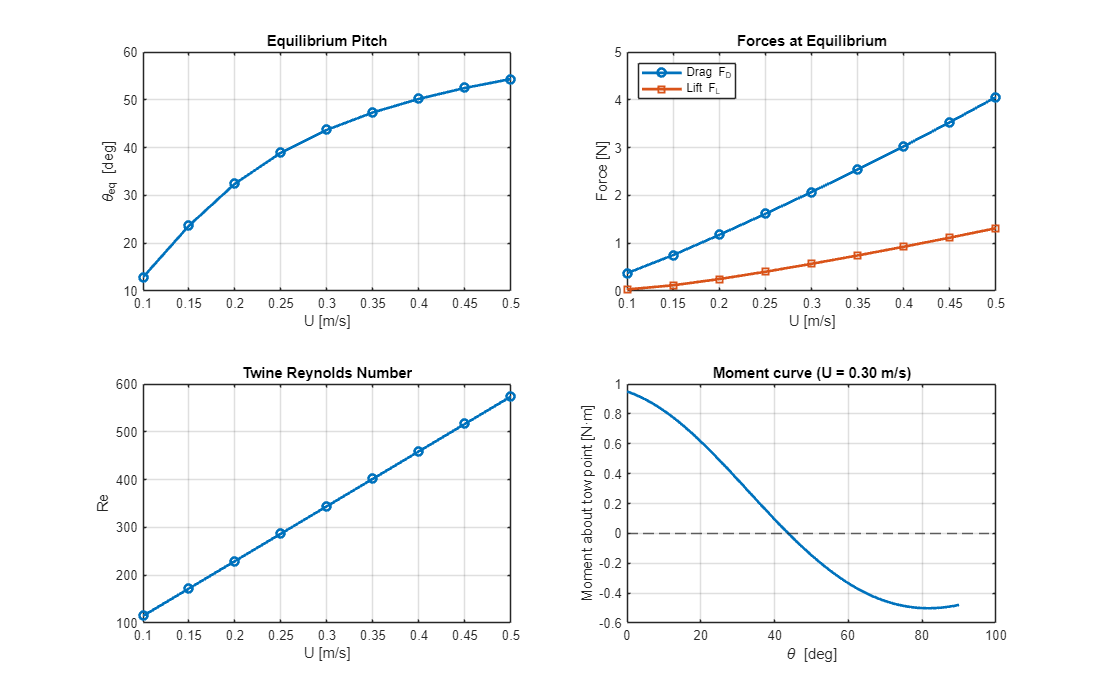

figure('Position',[100 100 1100 700]);
subplot(2,2,1);
plot(U_array, rad2deg(theta_eq), 'o-', 'LineWidth', 2);
grid on; xlabel('U [m/s]'); ylabel('\theta_{eq} [deg]'); title('Equilibrium Pitch');

subplot(2,2,2);
plot(U_array, FD_eq, 'o-', 'LineWidth', 2); hold on;
plot(U_array, FL_eq, 's-', 'LineWidth', 2);
grid on; xlabel('U [m/s]'); ylabel('Force [N]'); title('Forces at Equilibrium');
legend('Drag F_D','Lift F_L','Location','northwest');

subplot(2,2,3);
plot(U_array, Re_array, 'o-', 'LineWidth', 2);
grid on; xlabel('U [m/s]'); ylabel('Re'); title('Twine Reynolds Number');

subplot(2,2,4);
% Show moment curve at mid velocity for sanity check
U_rep = U_array(round(end/2));
q_rep = 0.5*rho*U_rep^2;
Re_rep = (dw*U_rep)/(nu*(1 - Sn));
Re_rep = max(Re_rep, 32);
xrep = log10(Re_rep);
CD_cyl_rep = -78.46675 + 254.73873*xrep - 327.88640*xrep^2 + 223.64577*xrep^3 ...
    - 87.92234*xrep^4 + 20.00769*xrep^5 - 2.44894*xrep^6 + 0.12479*xrep^7;
C0_rep = CD_cyl_rep * (Sn*(2-Sn)) / (2*(1-Sn)^2);
CN45_rep = C0_rep*cos(pi/4)^2;
CT45_rep = (4*CN45_rep)/(8+CN45_rep);
CL45_rep = CN45_rep*sin(pi/4) - CT45_rep*cos(pi/4);
a1 = 1-a3;
CD_of_rep = @(th) max( C0_rep*(a1*cos(th)+a3*cos(3*th)), 0 );
CL_of_rep = @(th) CL45_rep*(sin(2*th)+b4*sin(4*th));
FD_of_rep = @(th) CD_of_rep(th)*q_rep*A_net;
FL_of_rep = @(th) CL_of_rep(th)*q_rep*A_net;
moment_rep = @(th) ...
    + FD_of_rep(th) * (x_cp_frac*net_depth*cos(th)) ...
    - FL_of_rep(th) * (x_cp_frac*net_depth*sin(th)) ...
    + W_net_eff * (x_cg_net*net_depth*sin(th)) ...
    + W_sinker_eff * (x_cg_sinker*net_depth*sin(th));
th = linspace(0, pi/2, 200);
plot(rad2deg(th), arrayfun(moment_rep, th), 'LineWidth', 2); grid on;
xlabel('\theta [deg]'); ylabel('Moment about tow point [N·m]');
title(sprintf('Moment curve (U = %.2f m/s)', U_rep));
yline(0,'--');